# Simulink for Building Hardware Projects

Simulation is essential in designing all engineering systems. This enables quick design iterations at a low cost. In some instances, simulation is almost necessary to enable design. For instance, the self-balancing motorcycle is inherently an "unstable" system. A control algorithm is necessary to stabilize the system. Tuning the control gains on the real hardware for such a system is near impossible. In this scenario, simulation is helpful in two ways:

- Understanding and analyzing the system dynamics

- Designing and tuning algorithms quickly without causing harm to the hardware

Let's take a closer look at our motorcycle.

## Modeling the System

Open the simulation model:

motorcycleSim
set_param('motorcycleSim','StopTime',num2str(10));
set_param('motorcycleSim', 'EnablePacing', 'off')

 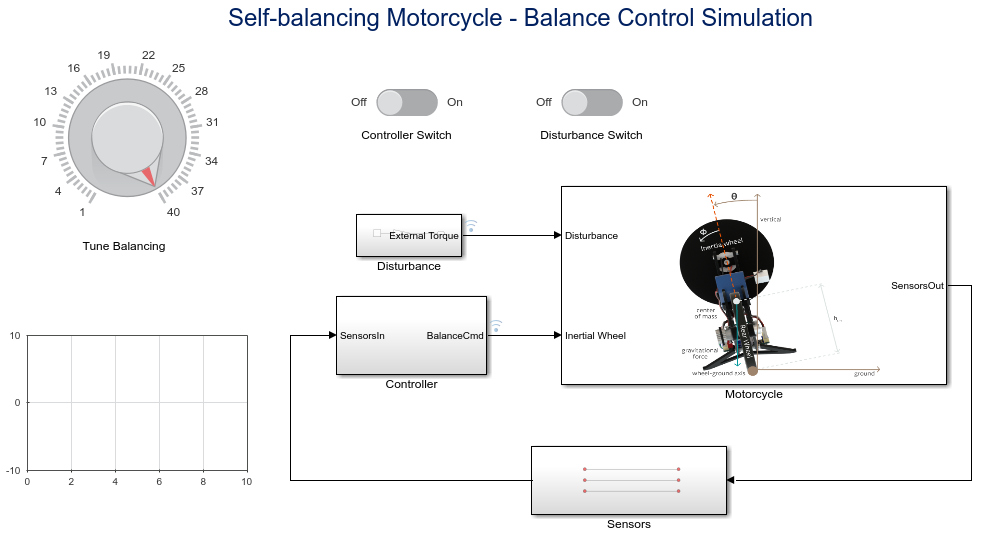

This is a Simulink model of the Motorcycle. We have modeled the complete system: the motorcycle, sensors, and balancing controller. We can inject a disturbance, and we can enable and tune the balancing controller.

Lets zoom in on the Motorcycle block (select block and use keyboard shortcut (spacebar +f) to zoom in). 

set_param('motorcycleSim/Motorcycle','Selected','on')
set_param(gcs,'ZoomFactor','FitSelection')

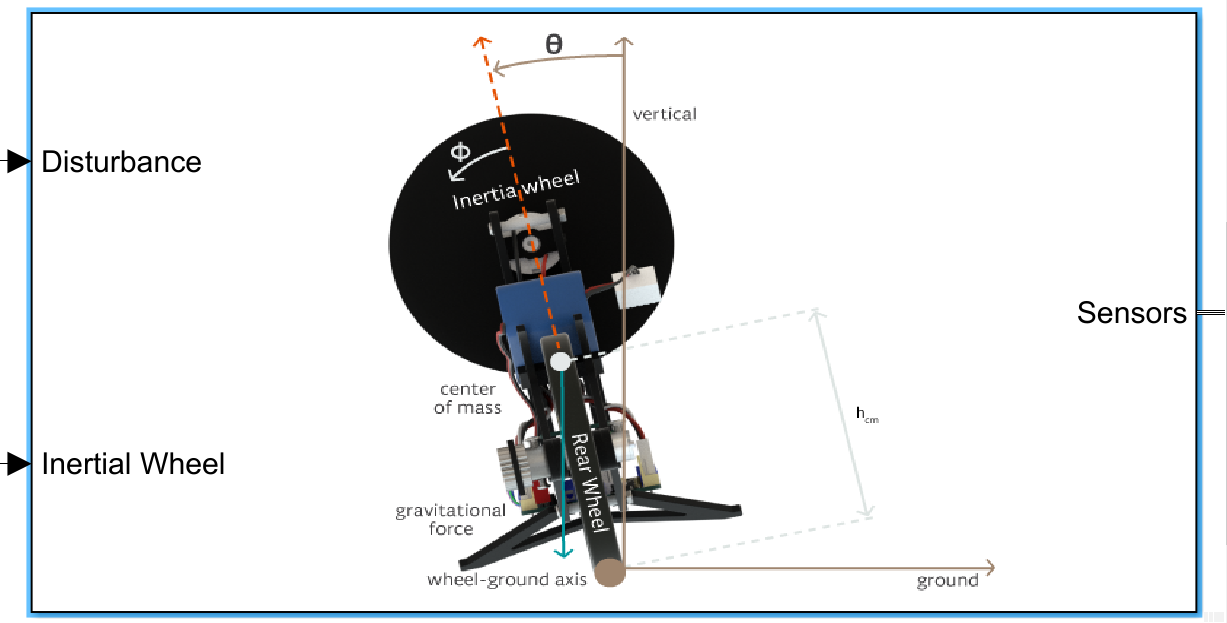

We have modeled the motorcycle as an inverted pendulum. The most important variable shown here is the lean angle, $\theta$, which is equal to 0 degrees when the motorcycle is perfectly upright, positive when the motorcycle leans counterclockwise when viewed from behind, and negative when the motorcycle leans clockwise. A derived quantity from this is the lean angle rate, $\dot{\theta}$.Another important angle is the rotational displacement of the inertia wheel, $\phi$. As the inertia wheel rotates relative to the rest of the motorcycle, $\phi$ varies in value, where positive displacement is defined as counterclockwise. Now the rate at which this displacement occurs $\dot{\phi}$ , is the control variable of the system.

Look into the subsystem to see how it is modeled. 

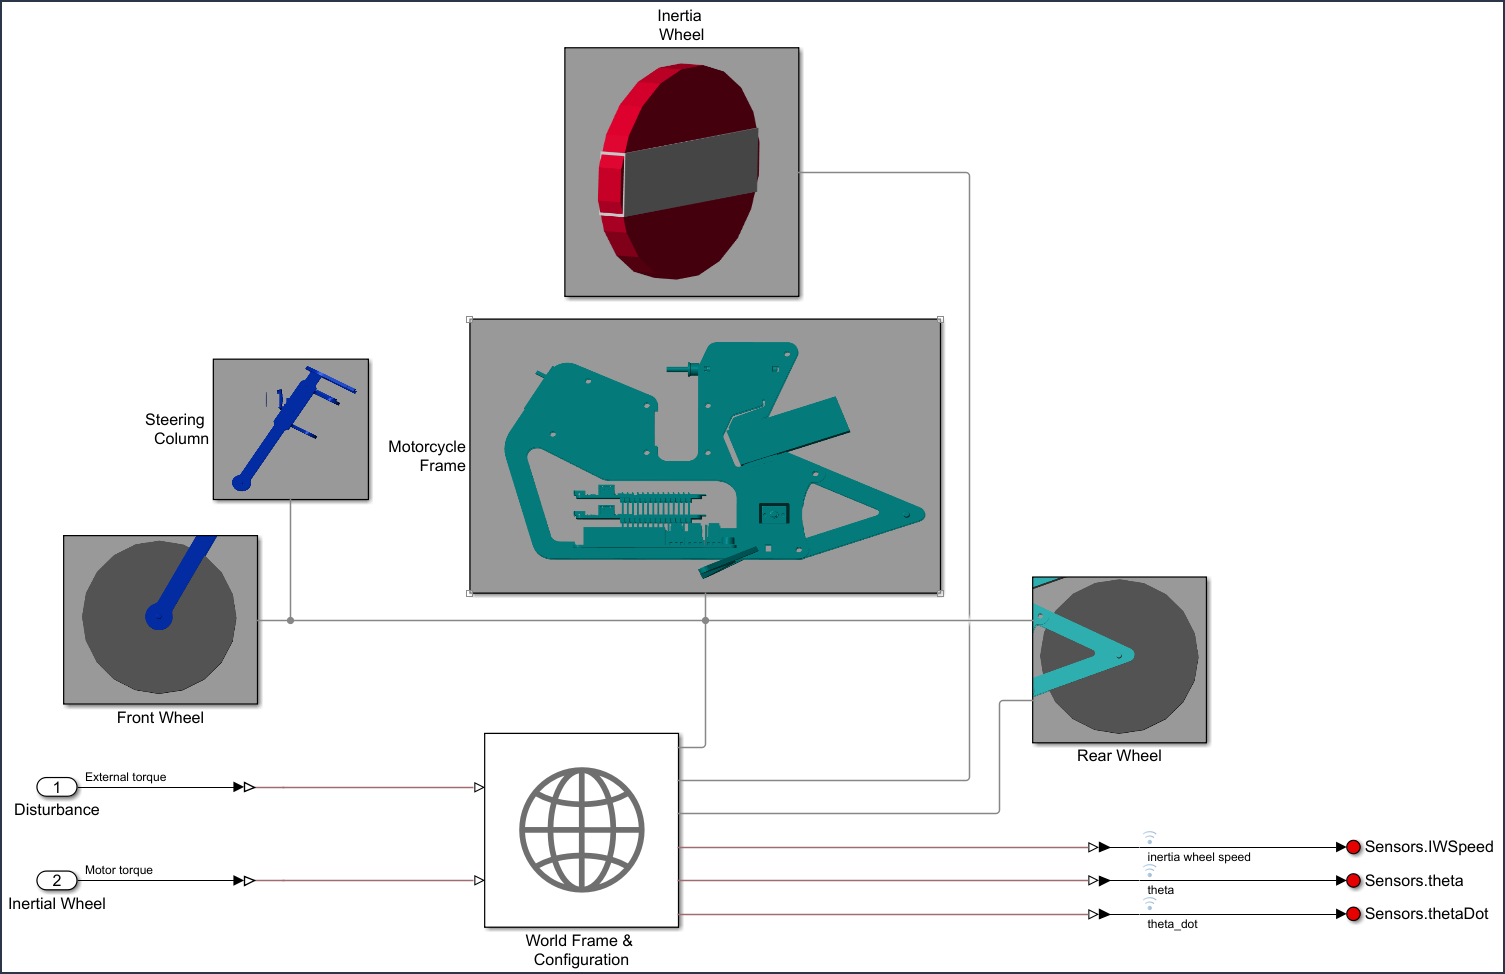

The model contains physical components for the rear wheel, inertial wheel and motorcycle body. Simulink automatically derives the system equations for these components. This approach is called physical modeling and it is different from the previous example, where we represented the rover by implementing our own set of differential equations. With Simulink you can combine these approaches to model electrical, mechanical, magnetic, and other types of systems. Note that with physical modeling you can import the system geometry from CAD models as shown in this example.

## Simulate and Analyze the Unstable System

Let's see the motorcycle response without a balancing algorithm and without external disturbances. In the model, turn **OFF** the balancing and disturbance controls and press the play button.

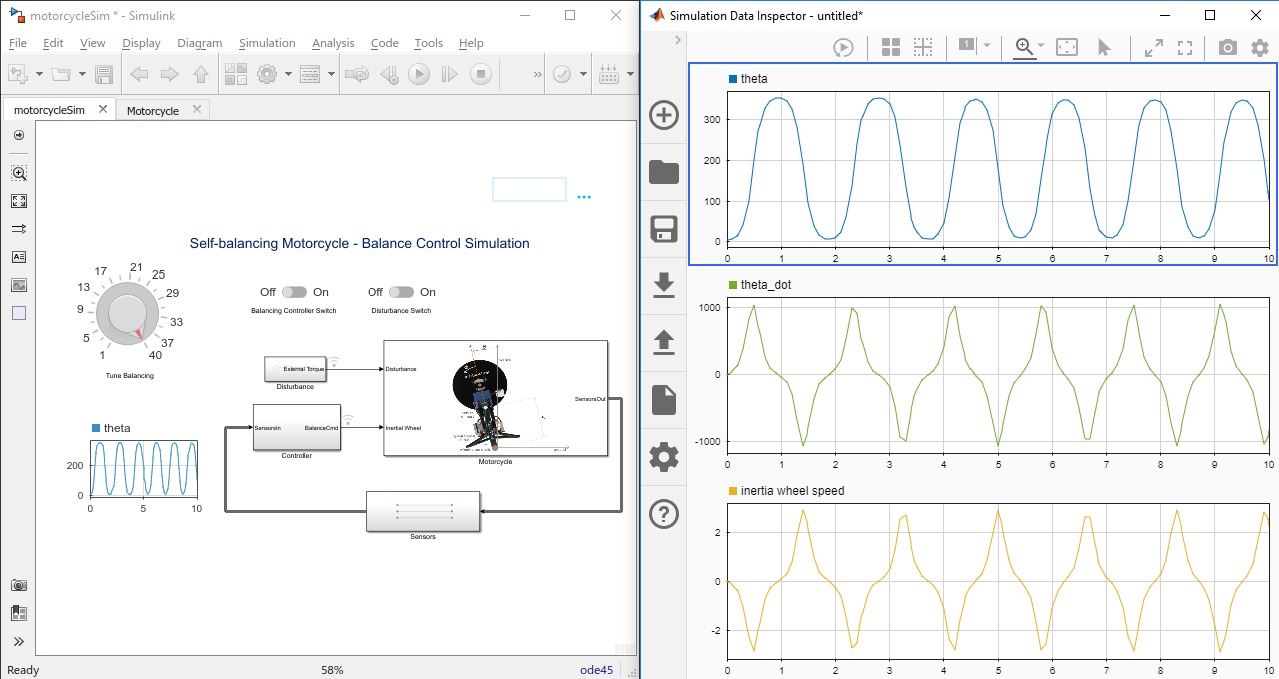

balancing   = 0; 
disturbance = 0;

Run the model.

set_param('motorcycleSim/Controller/Scale Down','Gain',num2str(balancing*0.02));
set_param('motorcycleSim/Disturbance/Scale Down','Gain',num2str(disturbance*0.1));
sim('motorcycleSim')

See the value of $\theta$ for the unstable system. You can see the sinusoidal behavior:

plot(logsout{2}.Values)

## Use a Controller to Make the System Stable 

We will use a PD controller to stabilize the motorcycle. A PD controller is a modified version of a PID that only includes the proportional and derivative terms. 

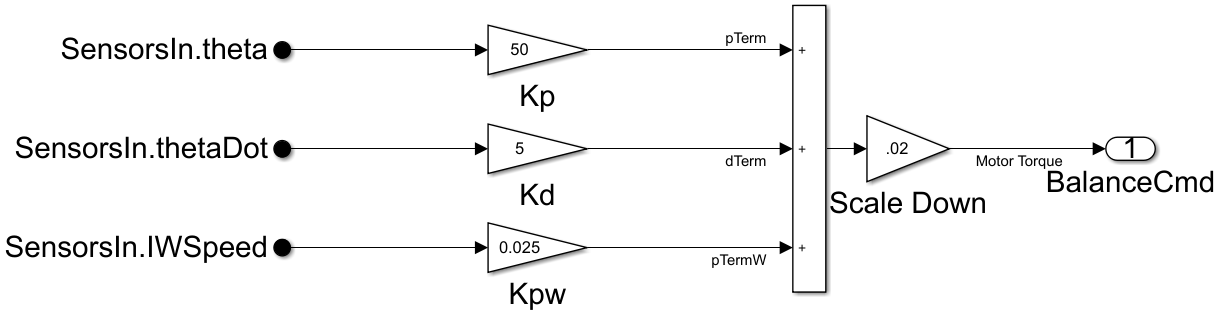

### Simulate and Analyze Again!

Turn **ON** the balancing and disturbance controls in the model, and press the play button to see the motorcyle response with a controller and with external disturbances.

balancing   = 1;
disturbance = 1;

Run the model.

set_param('motorcycleSim/Controller/Scale Down','Gain',num2str(balancing*0.02));
set_param('motorcycleSim/Disturbance/Scale Down','Gain',num2str(disturbance*0.1));
set_param('motorcycleSim/Controller/Kp','Gain',num2str(1));
sim('motorcycleSim')

See the value of $\theta$ for the stable system. You can see with external disturbances, the system is still stable with $\theta$ hovering around 0. But can we get a better response?

plot(logsout{2}.Values)

### Tune the Controller

Now let's tune the proportional gain of the controller as the model runs to improve our response. This tuning is done interactively with the knob control in the model. Sometimes Simulink runs simulations too fast to tune parameters or visualize results comfortably. Fortunately, we can control the control the pace of the simulation to make visualization of resutls easier. For tuning and visualizing, we will set the simulation pace to 1 simulation second per wall clock second. 

Press the play button, tune the controller, and checkout the results.

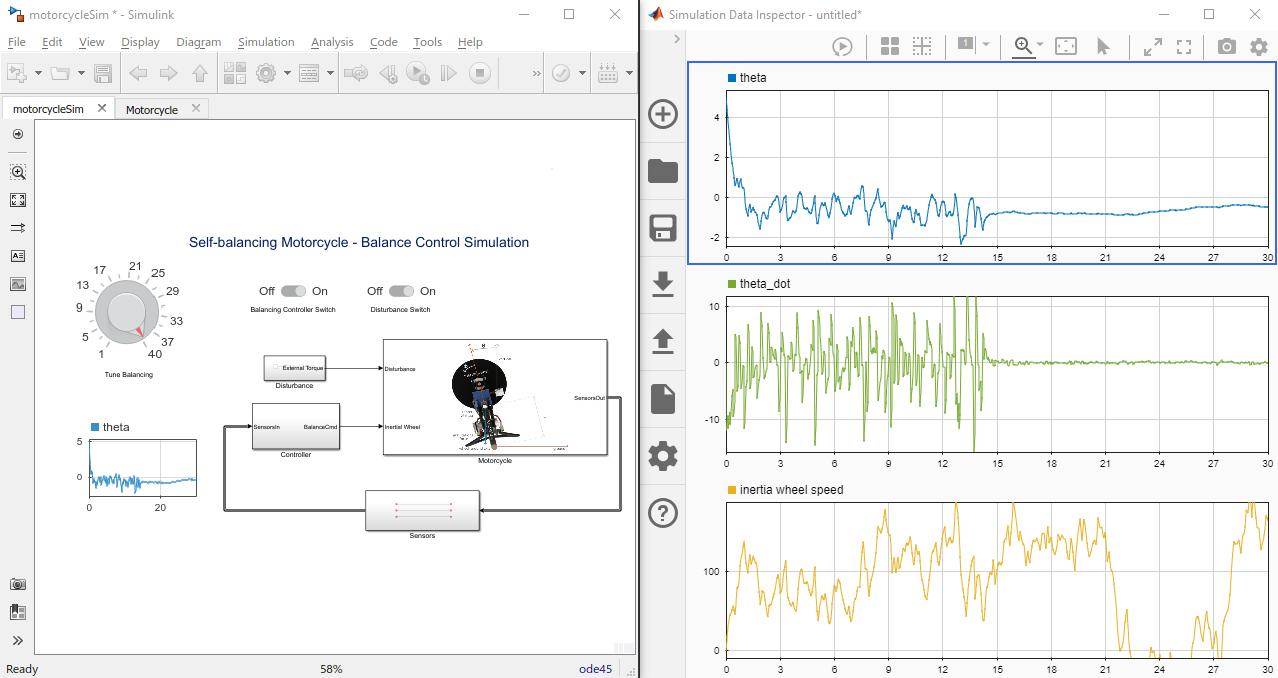

set_param('motorcycleSim','StopTime',num2str(30));
set_param('motorcycleSim', 'EnablePacing', 'on')
set_param('motorcycleSim','PacingRate',num2str(1));
sim('motorcycleSim')
plot(logsout{2}.Values)

## Working with the Hardware

Using simulation, we proved that our balancing algorithm works. It is time to shift our focus to hardware! Programming can be a challenge for engineers when working with embedded hardware. Writing device drivers and communication protocols is not an easy task and nor is it a completely necessary skill when building hardware projects, when all we are trying to do is applying algorithms on the hardware. Simulink makes it easy to program hardware with just the click of a button. 

For our example, since we will be using Arudino to program the motorcycle, let's look at these libraries. The motorcycle needs the base Arduino library:

arduinorootlib

And the MKR library:

mkrmotorcarrierlib

Now let's look at the hardware model and see how it is different from the simulation model:

motorcycleHW

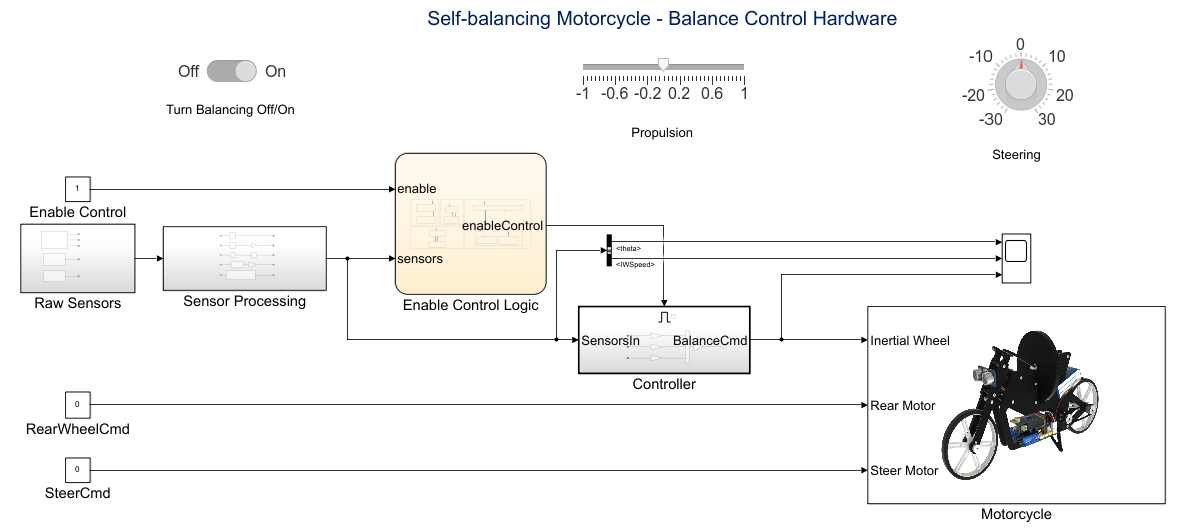

### Communicating with the Sensors and Motor Using Blocks

The first thing we can see on the sensor side is that there are now 2 subsystems. One subsystem (Raw Sensors) gets the sensor inputs. Here is where we are using the sensor blocks from the hardware support package:

open_system('motorcycleHW/Raw Sensors')

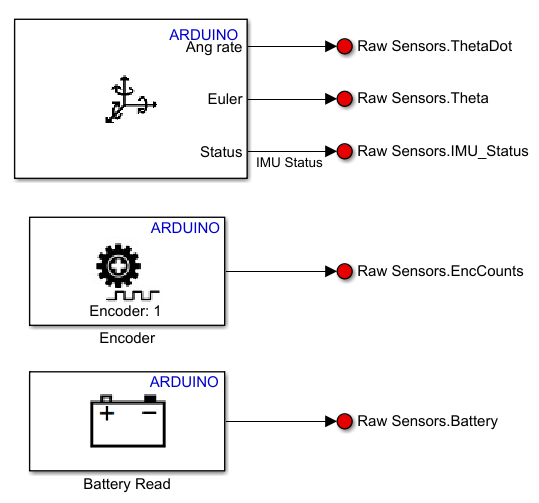

There is also a Sensor Processing subsystem to get derived values from the hardware because sensors may not always provide measurment in the form that you want or need:

open_system('motorcycleHW/Sensor Processing')

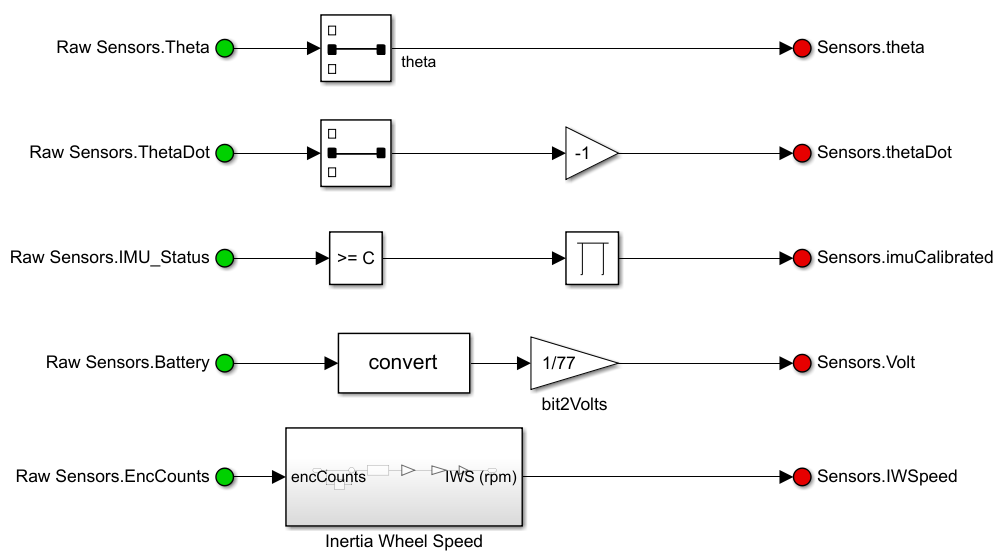

Note that Motorcycle subsystem in the hardware model is different than the one in the simulation model, and not just the picture. In this hardware model, we use blocks to send control commands to the motors instead of using a virtual representation of the motorcycle. Our intention now is to communicate with the actual hardware.

open_system('motorcycleHW/Motorcycle')

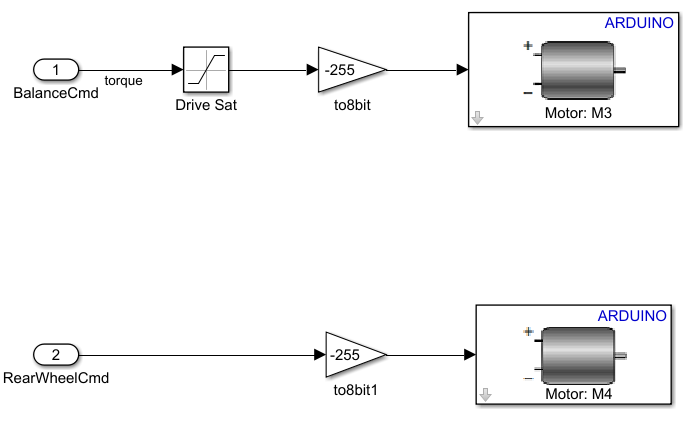

### Controls

The Controller subsystem is the same as the one in the simulation model. Note that simulation may not always exactly match the hardware behavior, so some tuning may be necessary for your controller.

open_system('motorcycleHW/Controller')

The biggest addition in the hardware model when compared to the simulation model is the presence of the "Enable Control Logic". 

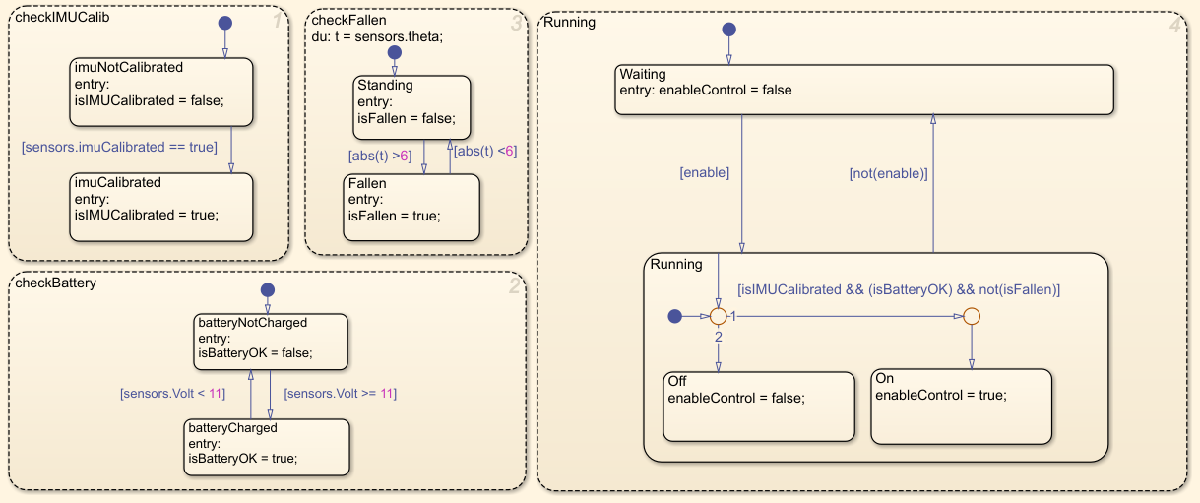

In Simulink, you can implement supervisory control algorithms in a graphical way, which can simplify the process of programming, debugging, and executing that logic. This graphical implementation can be used for:

- Sequential tasks. For e.g. here we are first calibrating the IMU sensor, then ckecing the battery etc. And finally running the self-balancing algorithm.

- Event-based logic. For e.g. here we are doing actions based on specific events such as if the motorcycle has fallen, if the IMU is calibrated etc. 

If we were to implement this supervisory control logic with textual programming, then the number of if-else and switch case statements would be quite large. 

#### To calibrate the IMU, you need to calibrate the magnetometer and accelerometer. 

    1. To calibrate the magnetometer, hold the motorcycle vertically in a position where the Arduino board is parallel to the ground and move the motorcycle along the Figure 8 path shown below. 

        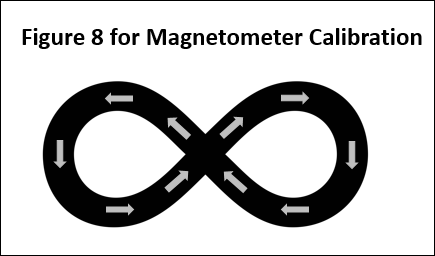

    2. To calibrate the accelerometer, hold the motorcycle vertically in a position where the Arduino board is parallel to the ground. This is Stable position 1 in the image below. Hold the motorcycle for a few seconds in each of the 6 stable positions shown below.  

        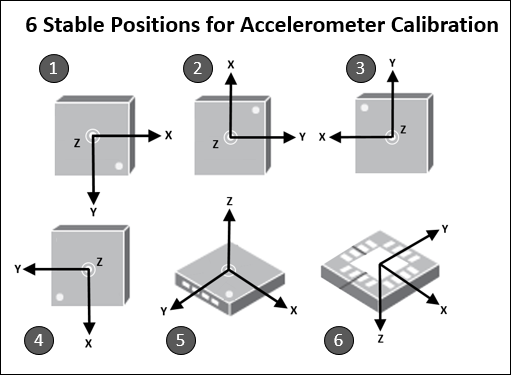

Repeat the process, till the isIMUCalibrated flag becomes true. *Note: This process needs to be repeated every time the isIMUCalibrated flag is false. *

### Deployment - Running on the Hardware

With Simulink, you can deploy the standalone algorithm on the hardware with a single click of a button. You can also run this model in External Model to monitor signals and tune parameters in real-time while the algorithm is running on the hardware.

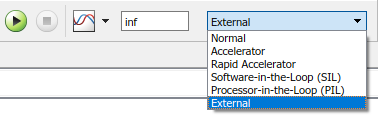

% sim('motorcycleHW');

With the model set to External Mode, click on the Run button to automatically generate code from the model and download it to the hardware. This simulation mode establishes a communication interface back to our Simulink model, so we can monitor the signals from the hardware in the model.

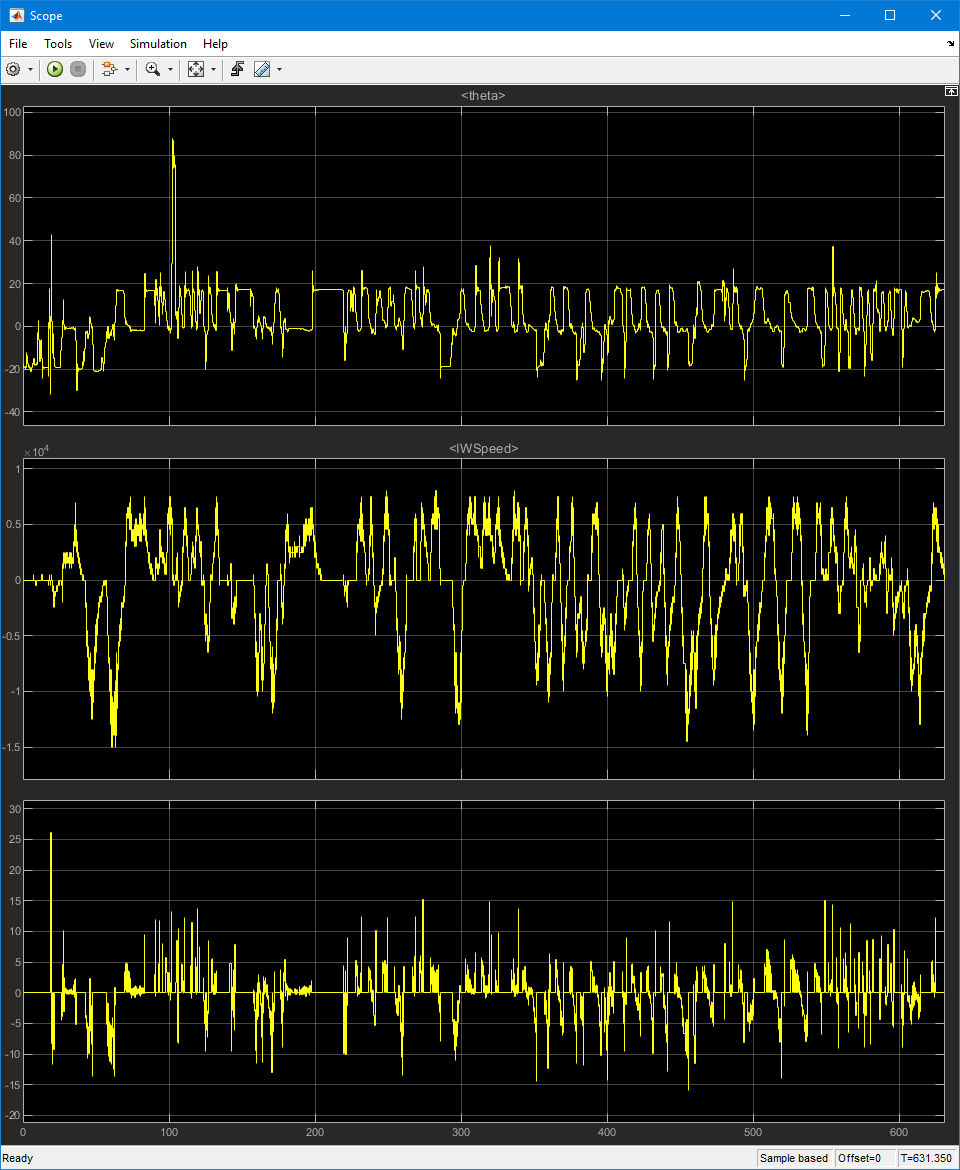

You can also visualize the execution of the supervisory logic as the algorithm transitions between states:

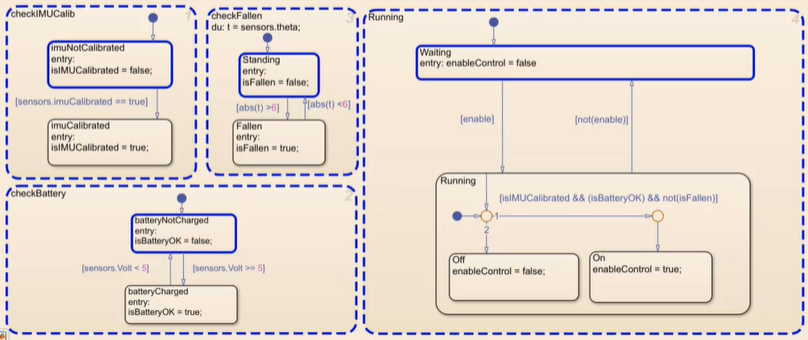

In this supervisory logic chart we are implementing several "states" of the self-balancing motorcycle as follows:

- *checkIMUCalib*: We can perform any dynamic action with the robot only when the IMU sensor is calibrated. 

- *checkBattery*: We should not control the inertia wheel if the battery voltage is less than the specified value.

- *checkFallen*: If the $\theta$ value is greater than a threshold, then we consider that the motorcycle has fallen and turn off the control (the motorcycle can't restabilize itself once fallen).

- *Running*: This is the main state where the self-balancing happens. We use the flags from all the previous states to turn on the balancing control.

You can also tune parameters in realtime and see the effect of it on the algorithm running on the hardware. Note that the motorcyle is only self-balancing in place. We are also feeding in a rear wheel propulsion command in the model. Even though by default, this is 0. Let's use the slider here to set it to a non zero positive value. This makes the bike move forward!

% set_param('motorcycleHW/RearWheelCommand','Value','0.4');

You can try it for a negative value as well to see it move in the reverse direction.

% set_param('motorcycleHW/RearWheelCommand','Value','-0.4');